clear;
close all;
clc;
sympref('FloatingPointOutput',false);
sympref('AbbreviateOutput',true);
format LongEng;

frequency_step = 0.1; % in MHz

input_dir  = "../input_cal/Datasheet_HornAnttena_ETS3115/"

input_dir = "../input_cal/Datasheet_HornAnttena_ETS3115/"

output_dir = "../output/"

output_dir = "../output/"


Data_1mH  = readtable(append(input_dir,'TAR-3115.xlsx'), 'Range', 'B5:E28', 'ReadVariableNames',true);

Data_1mV  = readtable(append(input_dir,'TAR-3115.xlsx'), 'Range', 'G5:J28', 'ReadVariableNames',true);

Data_3mH  = readtable(append(input_dir,'TAR-3115.xlsx'), 'Range', 'K5:N28', 'ReadVariableNames',true);

Data_3mV  = readtable(append(input_dir,'TAR-3115.xlsx'), 'Range', 'P5:S28', 'ReadVariableNames',true);

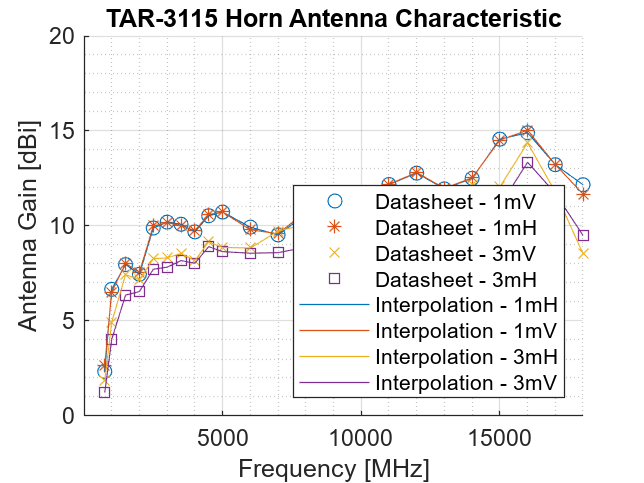


% https://jp.mathworks.com/help/matlab/interpolation.html

Data_1mV_Interp_Freq  = Data_1mV.Frequency_MHz_(1):frequency_step:Data_1mV.Frequency_MHz_(end);  % sample to 0.1 MHz step
Data_1mH_Interp_Freq  = Data_1mH.Frequency_MHz_(1):frequency_step:Data_1mH.Frequency_MHz_(end);  % sample to 0.1 MHz step
Data_3mV_Interp_Freq  = Data_3mV.Frequency_MHz_(1):frequency_step:Data_3mV.Frequency_MHz_(end);  % sample to 0.1 MHz step
Data_3mH_Interp_Freq  = Data_3mH.Frequency_MHz_(1):frequency_step:Data_3mH.Frequency_MHz_(end);  % sample to 0.1 MHz step

%yy_spline       = spline(   Data_1mH.Frequency_MHz_, Data_1mH.Gain_dBi_, xx_step_interp);

Data_1mV_Interp_Gain_dBi    = interp1( Data_1mV.Frequency_MHz_, Data_1mV.Gain_dBi_, Data_1mV_Interp_Freq );
Data_1mH_Interp_Gain_dBi    = interp1( Data_1mH.Frequency_MHz_, Data_1mH.Gain_dBi_, Data_1mH_Interp_Freq );
Data_3mV_Interp_Gain_dBi    = interp1( Data_3mV.Frequency_MHz_, Data_3mV.Gain_dBi_, Data_3mV_Interp_Freq );
Data_3mH_Interp_Gain_dBi    = interp1( Data_3mH.Frequency_MHz_, Data_3mH.Gain_dBi_, Data_3mH_Interp_Freq );

hold on;
plot(Data_1mV.Frequency_MHz_,Data_1mV.Gain_dBi_,'o','DisplayName','Datasheet - 1mV','Color',"#0072BD");
plot(Data_1mH.Frequency_MHz_,Data_1mH.Gain_dBi_,'*','DisplayName','Datasheet - 1mH','Color',"#D95319");
plot(Data_3mV.Frequency_MHz_,Data_3mV.Gain_dBi_,'x','DisplayName','Datasheet - 3mV','Color',"#EDB120");
plot(Data_3mH.Frequency_MHz_,Data_3mH.Gain_dBi_,'square','DisplayName','Datasheet - 3mH','Color',"#7E2F8E");

plot(Data_1mV_Interp_Freq, Data_1mV_Interp_Gain_dBi,'DisplayName','Interpolation - 1mH', 'Color', "#0072BD");
plot(Data_1mH_Interp_Freq, Data_1mH_Interp_Gain_dBi,'DisplayName','Interpolation - 1mV', 'Color', "#D95319");
plot(Data_3mV_Interp_Freq, Data_3mV_Interp_Gain_dBi,'DisplayName','Interpolation - 3mH', 'Color', "#EDB120");
plot(Data_3mH_Interp_Freq, Data_3mH_Interp_Gain_dBi,'DisplayName','Interpolation - 3mV', 'Color', "#7E2F8E");


axis on
grid on
grid minor
xlim([1 18000]);
ylim([0 20]);

title('TAR-3115 Horn Antenna Characteristic');
xlabel('Frequency [MHz]');
ylabel('Antenna Gain [dBi]');
legend('Location','southeast');

saveas(gcf,append(append(input_dir,'TAR-3115_HornAntenna.png')));


% --- Data exporting

Data_1mV_Interp = transpose([Data_1mV_Interp_Freq; Data_1mV_Interp_Gain_dBi]);
Data_1mH_Interp = transpose([Data_1mH_Interp_Freq; Data_1mH_Interp_Gain_dBi]);
Data_3mV_Interp = transpose([Data_3mV_Interp_Freq; Data_3mV_Interp_Gain_dBi]);
Data_3mH_Interp = transpose([Data_3mH_Interp_Freq; Data_3mH_Interp_Gain_dBi]);

writematrix(Data_1mV_Interp, append(input_dir,'TAR-3115_Data_1mV_Interpolation.csv'));
writematrix(Data_1mH_Interp, append(input_dir,'TAR-3115_Data_1mH_Interpolation.csv'));
writematrix(Data_3mV_Interp, append(input_dir,'TAR-3115_Data_3mV_Interpolation.csv'));
writematrix(Data_3mH_Interp, append(input_dir,'TAR-3115_Data_3mH_Interpolation.csv'));

% --- Exporting to SQLite
filename_db = 'antmeas.db';
filename = append(output_dir,filename_db);
conn = sqlite(filename);      % auto-commit mode

%conn = sqlite('TAR-3115_Dataset.db','create');      % auto-commit mode

data = table(transpose(Data_1mV_Interp_Freq),transpose(Data_1mV_Interp_Gain_dBi),'VariableNames',["frequency_MHz" "gain_dBi"]);
sqlwrite(conn, 'TAR3115_dataset_Data1mV', data);
data = table(transpose(Data_1mH_Interp_Freq),transpose(Data_1mH_Interp_Gain_dBi),'VariableNames',["frequency_MHz" "gain_dBi"]);
sqlwrite(conn, 'TAR3115_dataset_Data1mH', data);

data = table(transpose(Data_3mV_Interp_Freq),transpose(Data_3mV_Interp_Gain_dBi),'VariableNames',["frequency_MHz" "gain_dBi"]);
sqlwrite(conn, 'TAR3115_dataset_Data3mV', data);
data = table(transpose(Data_3mH_Interp_Freq),transpose(Data_3mH_Interp_Gain_dBi),'VariableNames',["frequency_MHz" "gain_dBi"]);
sqlwrite(conn, 'TAR3115_dataset_Data3mH', data);


close(conn);